Przyjmijmy dla wariantu (a) dwukryterialnego:

F1(x,y)=x^2+y^2, F2(x,y)=(x−1)^2+2(y+0.5)^2

Domena:

U = [-1,1]^2

Dla wariantu (b) trzykryterialnego:

G_1(x,y,z)=x^2+y^2+z^2 

G_2(x,y,z)=(x-1)^2 + 2(y+0.5)^2 + z^2 

G_3(x,y,z)=x+y+z

Domena:

U=[-1,1]^3

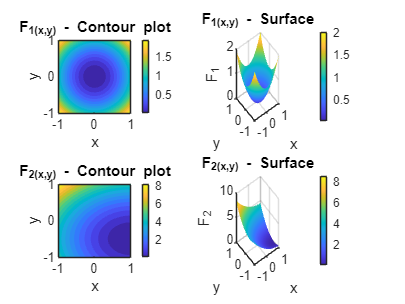

figure(); clf;

% ------ siatka w domenie [-1,1]² ------
[xg, yg] = meshgrid(linspace(-1,1,100));
F1g = xg.^2 + yg.^2;
F2g = (xg-1).^2 + 2*(yg+0.5).^2;

%% ------------------------- F1: kontury ------------------------------- %%
subplot(2,2,1)
contourf(xg, yg, F1g, 20, 'LineColor','none')
title('F_1(x,y) - Contour plot')
xlabel('x'); ylabel('y'); colorbar
axis equal tight

%% ------------------------- F1: powierzchnia -------------------------- %%
subplot(2,2,2)
surf(xg, yg, F1g)
shading interp
title('F_1(x,y) - Surface')
xlabel('x'); ylabel('y'); zlabel('F_1')
colorbar

%% ------------------------- F2: kontury ------------------------------- %%
subplot(2,2,3)
contourf(xg, yg, F2g, 20, 'LineColor','none')
title('F_2(x,y) - Contour plot')
xlabel('x'); ylabel('y'); colorbar
axis equal tight

%% ------------------------- F2: powierzchnia -------------------------- %%
subplot(2,2,4)
surf(xg, yg, F2g)
shading interp
title('F_2(x,y) - Surface')
xlabel('x'); ylabel('y'); zlabel('F_2')
colorbar

a) problem dwukryterialny

Weighted sum

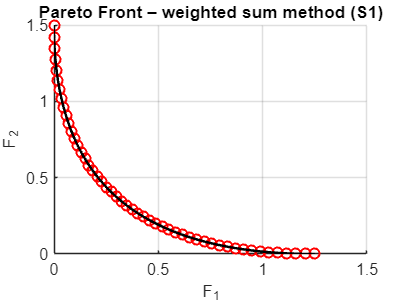

clear, clc, close all
hold on

% ---- Domain ----
x0 = [0 0];
LB = [-1 -1];
UB = [ 1  1];

options = optimset('LargeScale','off','MaxFunEvals',5000,...
    'TolFun',1e-7,'TolCon',1e-7,'Display','off');

% ---- weight parameter λ ----
n = 50;
w1 = linspace(0,1,n);

xopt = zeros(n,2);
Fval = zeros(n,2);

for i=1:n
    lambda = w1(i);
    [xopt(i,:), ~] = fmincon(@(u)obj(u,lambda), x0, [],[],[],[],...
                              LB,UB,[],options);
    Fval(i,1) = F1(xopt(i,:));
    Fval(i,2) = F2(xopt(i,:));
end

figure(1); hold on; grid on
plot(Fval(:,1), Fval(:,2), 'ro-', 'LineWidth',1.2)
xlabel('F_1'); ylabel('F_2')
title('Pareto Front – weighted sum method (S1)')
Fsp = fnplt(cscvn(Fval'));
plot(Fsp(1,:), Fsp(2,:), 'k-', 'LineWidth', 1.5);

epsilon ograniczeń

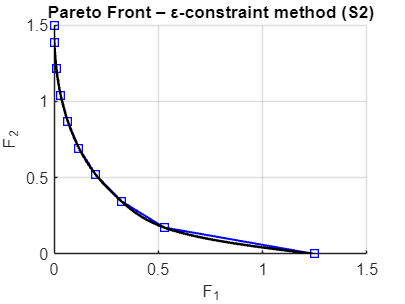

clear, clc, close all
hold on

x0 = [0 0];
LB = [-1 -1];
UB = [ 1  1];

options = optimset('LargeScale','off','MaxFunEvals',5000,...
    'TolFun',1e-7,'TolCon',1e-7,'Display','off');

% --- ε grid ----
n = 50;
eps_vals = linspace(min_eps(), max_eps(), n);

xopt = zeros(n,2);
Fval = zeros(n,2);

for i=1:n
    eps_i = eps_vals(i);

    [xopt(i,:), ~] = fmincon(@(u)F1(u), x0, [],[],[],[],...
                             LB,UB,@(u)nonlcon_eps(u,eps_i),options);

    Fval(i,1)=F1(xopt(i,:));
    Fval(i,2)=F2(xopt(i,:));
end

figure(2); hold on; grid on
plot(Fval(:,1), Fval(:,2), 'bs-','LineWidth',1.2)
xlabel('F_1'); ylabel('F_2')
title('Pareto Front – ε-constraint method (S2)')
Fsp = fnplt(cscvn(Fval'));
plot(Fsp(1,:), Fsp(2,:), 'k-', 'LineWidth', 1.5);

Skalowanie przez odległość

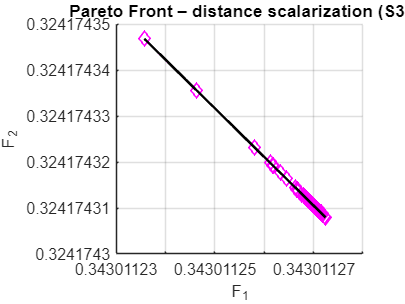

clear, clc, close all
hold on

x0 = [0 0];
LB = [-1 -1];
UB = [ 1  1];

options = optimset('LargeScale','off','MaxFunEvals',5000,...
    'TolFun',1e-7,'TolCon',1e-7,'Display','off');

x_dom = [0 0];          % punkt dominujący
n = 50;
lambda = linspace(0.1,2,n);

xopt = zeros(n,2);
Fval = zeros(n,2);

for i=1:n
    lam = lambda(i);
    [xopt(i,:), ~] = fmincon(@(u)norm_scalarization(u,x_dom,lam,2),...
                              x0,[],[],[],[],LB,UB,[],options);
    Fval(i,1)=F1(xopt(i,:));
    Fval(i,2)=F2(xopt(i,:));
end

figure(3); hold on; grid on
plot(Fval(:,1),Fval(:,2),'md-','LineWidth',1.2)
xlabel('F_1'); ylabel('F_2')
title('Pareto Front – distance scalarization (S3)')
Fsp = fnplt(cscvn(Fval'));
plot(Fsp(1,:), Fsp(2,:), 'k-', 'LineWidth', 1.5);

b) problem trzykryterialny

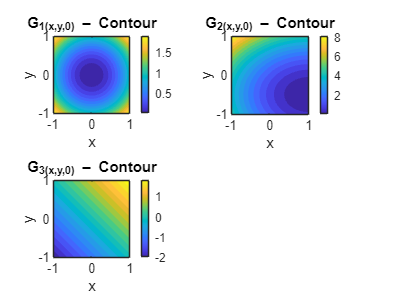

figure; clf;

xs = linspace(-1,1,80);
ys = xs;

[xg, yg] = meshgrid(xs,ys);

%% ---------- F1 cross-section G1(x,y,0) ----------
Z1 = xg.^2 + yg.^2;   % G1(x,y,0)

subplot(2,2,1)
contourf(xg, yg, Z1, 20, 'LineColor','none');
title('G_1(x,y,0) – Contour');
xlabel('x'); ylabel('y'); colorbar;
axis equal tight;

%% ---------- F2 cross-section G2(x,y,0) ----------
Z2 = (xg - 1).^2 + 2*(yg + 0.5).^2 + 0.^2;

subplot(2,2,2)
contourf(xg, yg, Z2, 20, 'LineColor','none');
title('G_2(x,y,0) – Contour');
xlabel('x'); ylabel('y'); colorbar;
axis equal tight;

%% ---------- F3 cross-section G3(x,y,0) ----------
Z3 = xg + yg + 0;

subplot(2,2,3)
contourf(xg, yg, Z3, 20, 'LineColor','none');
title('G_3(x,y,0) – Contour');
xlabel('x'); ylabel('y'); colorbar;
axis equal tight;

Weighted sum

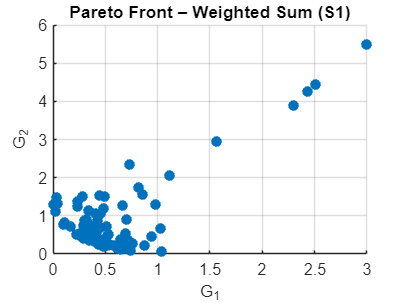

clear, clc, close all

x0 = [0 0 0];
LB = [-1 -1 -1];
UB = [ 1  1  1];

options = optimset('Display','off','TolFun',1e-7,'TolCon',1e-7);

% weights on the unit simplex
n = 80;
w = rand(n,3);
w = w ./ sum(w,2);

Xopt = zeros(n,3);
Gval = zeros(n,3);

for i=1:n
    wi = w(i,:);
    [Xopt(i,:), ~] = fmincon(@(u) scalar_w(u,wi), x0,[],[],[],[],LB,UB,[],options);

    Gval(i,1)=G1(Xopt(i,:));
    Gval(i,2)=G2(Xopt(i,:));
    Gval(i,3)=G3(Xopt(i,:));
end

figure; hold on; grid on
scatter3(Gval(:,1),Gval(:,2),Gval(:,3),40,'filled')
xlabel('G_1'); ylabel('G_2'); zlabel('G_3')
title('Pareto Front – Weighted Sum (S1)')

epsilon

minG1�(x,y,z)

G2(x,y,z)≤ε2

G3(x,y,z)≤ε3�

clear, clc, close all

x0 = [0 0 0];
LB = [-1 -1 -1];
UB = [ 1  1  1];

options = optimset('Display','off','TolFun',1e-7,'TolCon',1e-7);

% ranges for epsilons
eps2 = linspace( min_G2(), max_G2(), 15 );
eps3 = linspace( min_G3(), max_G3(), 15 );

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: -632741492463149473936482746465621925523677687840768.000000 



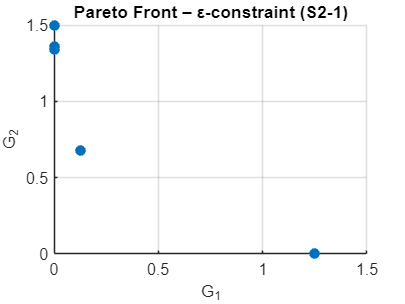


Gval = [];
Xopt = [];

for i=1:length(eps2)
    for j=1:length(eps3)

        e2 = eps2(i);
        e3 = eps3(j);

        [xopt, ~] = fmincon(@(u) G1(u), x0,[],[],[],[],...
            LB,UB,@(u) nonlcon_eps_3D(u,e2,e3), options);

        Xopt = [Xopt ; xopt];
        Gval = [Gval ; G1(xopt), G2(xopt), G3(xopt)];

    end
end

figure; hold on; grid on
scatter3(Gval(:,1),Gval(:,2),Gval(:,3),40,'filled')
xlabel('G_1'); ylabel('G_2'); zlabel('G_3')
title('Pareto Front – ε-constraint (S2-1)')

Distance scalarization

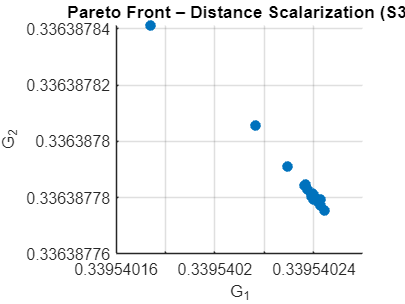

clear, clc, close all

x0 = [0 0 0];
LB = [-1 -1 -1];
UB = [ 1  1  1];

options = optimset('Display','off','TolFun',1e-7,'TolCon',1e-7);

x_dom = [0 0 0];
lambda = linspace(0.1,2,40);

Gval = [];
Xopt = [];

for i=1:length(lambda)

    lam = lambda(i);

    [xopt, ~] = fmincon(@(u) dist_scalar(u,x_dom,lam,2),...
                        x0,[],[],[],[],LB,UB,[],options);

    Xopt = [Xopt ; xopt];
    Gval = [Gval ; G1(xopt), G2(xopt), G3(xopt)];

end

figure; hold on; grid on
scatter3(Gval(:,1),Gval(:,2),Gval(:,3),40,'filled')
xlabel('G_1'); ylabel('G_2'); zlabel('G_3')
title('Pareto Front – Distance Scalarization (S3)')

function val = obj(u, lambda)
    val = lambda*F1(u) + (1-lambda)*F2(u);
end

function y = F1(u)
    x=u(1); y_=u(2);
    y = x.^2 + y_.^2;
end

function y = F2(u)
    x=u(1); y_=u(2);
    y = (x-1).^2 + 2*(y_+0.5).^2;
end

function [c,ceq] = nonlcon_eps(u, eps_val)
    c = F2(u) - eps_val;  % F2 ≤ ε
    ceq = [];
end

function m = min_eps()
    f = @(u)F2(u);
    [~,m] = fminsearch(f,[0 0]);
end

function M = max_eps()
    xs = linspace(-1,1,40);
    ys = xs;
    M = -inf;
    for i=1:length(xs)
        for j=1:length(ys)
            M = max(M, F2([xs(i),ys(j)]));
        end
    end
end

function val = norm_scalarization(u,xdom,lambda,p)
    F = [F1(u), F2(u)];
    val = lambda * norm(F - xdom, p);
end

function y = G1(u)
    x=u(1); y_=u(2); z=u(3);
    y = x.^2 + y_.^2 + z.^2;
end

function y = G2(u)
    x=u(1); y_=u(2); z=u(3);
    y = (x-1).^2 + 2*(y_+0.5).^2 + z.^2;
end

function y = G3(u)
    y = sum(u);     % x + y + z
end

function val = scalar_w(u,w)
    val = w(1)*G1(u) + w(2)*G2(u) + w(3)*G3(u);
end

function [c,ceq] = nonlcon_eps_3D(u,e2,e3)
    c = [ G2(u) - e2 ;
          G3(u) - e3 ];
    ceq = [];
end

function m = min_G2()
    f=@(u)G2(u);
    [~,m] = fminsearch(f,[0 0 0]);
end
function M = max_G2()
    xs=linspace(-1,1,10);
    M=-inf;
    for x=xs,for y=xs,for z=xs
        M=max(M,G2([x y z]));
    end,end,end
end

function m = min_G3()
    f=@(u)G3(u);
    [~,m] = fminsearch(f,[0 0 0]);
end
function M = max_G3()
    M = 3*1;   % simply x+y+z max = 1+1+1
end

function val = dist_scalar(u,xdom,lambda,p)
    G = [G1(u), G2(u), G3(u)];
    val = lambda * norm(G - xdom, p);
end